# 1.3.02 Программирование. Создание функций

В данном файле приведен код, который строит различные типы винтовых линий, и с помощью функции `planeProjection()` строит проекции фигур на координатные плоскости. Преобразуйте код, строящий винтовые линии, в функции, которые принимают на вход необходимые параметры. Вызовите эти функции, в результате вы долны получить 4 трехмерных графика.

## Построение графиков:

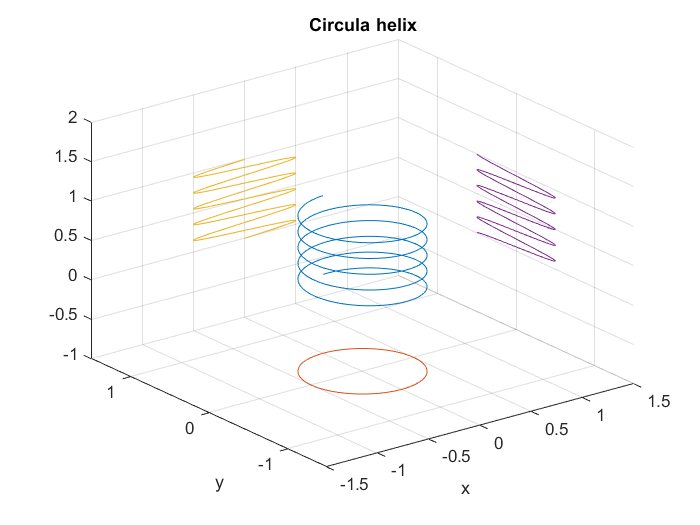

% Цилиндрическая винтовая линия
% Коническая винтовая линия
a = 0.5;
c = 5.0;
t = 0:0.01:10*pi;
circularHelix(a,c,t)

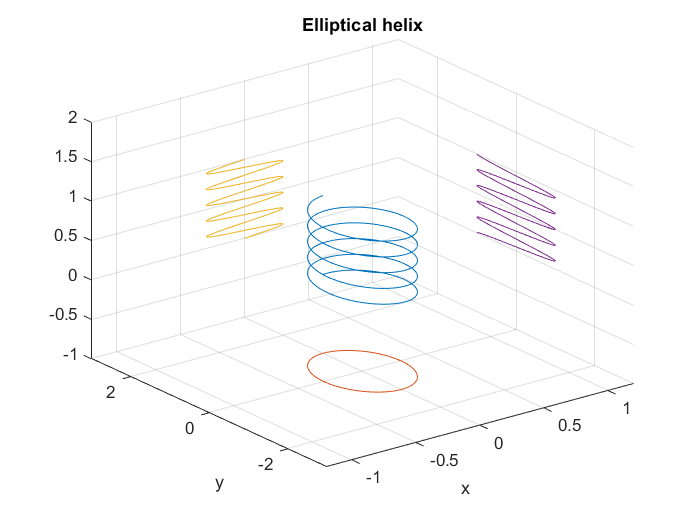

a = 0.3;
b = 1.0;
c = 5.0;
t = 0:0.01:10*pi;
ellipticalHelix(a,b,c,t)

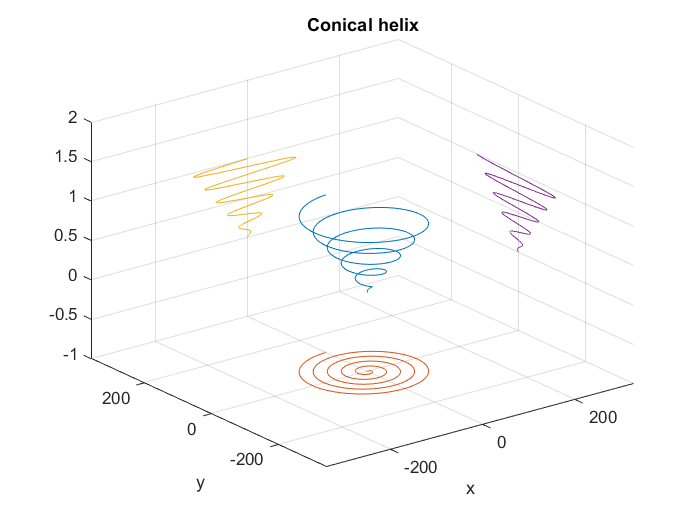

a = 0.5;
c = 5.0;
t = 0:0.01:10*pi;
conicalHelix(a,c,t)

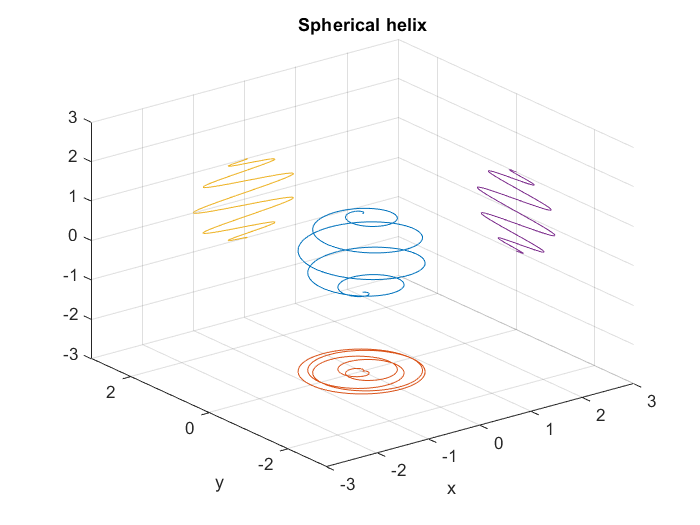

c = 5.0;
t = 0:0.01:10*pi;
sphericalHelix(c,t)

function circularHelix(a,c,t)
% Circular helix (right helicoid)

x = a*sin(t);
y = a*cos(t);
z = t/(2*pi*c);
figure(1)
plot3(x, y, z);
xlabel('x'); ylabel('y'); title('Circula helix');
grid on;
planeProjection()
end

function ellipticalHelix(a,b,c,t)
% Elliptical helix

x = a*sin(t);
y = b*cos(t);
z = t/(2*pi*c);
figure(2);
plot3(x, y, z);
xlabel('x'); ylabel('y'); title('Elliptical helix');
grid on;
planeProjection()
end

function conicalHelix(a,c,t)
% Conical helix

x = (a*t/2*pi*c).*sin(t);
y = (a*t/2*pi*c).*cos(t);
z = t/(2*pi*c);
figure(3);
plot3(x, y, z);
xlabel('x'); ylabel('y'); title('Conical helix');
planeProjection()
grid on;
end

function sphericalHelix(c,t)
% Spherical helix

x = sin(t/(2*c)).*cos(t);
y = sin(t/(2*c)).*sin(t);
z = cos(t/(2*c));
figure(4);
plot3(x, y, z);
xlabel('x'); ylabel('y'); title('Spherical helix');
grid on;
planeProjection()
end

function planeProjection()
ax = gca;
set(ax,'NextPlot','add');
colX = ax.Children.XData';
colY = ax.Children.YData';
colZ = ax.Children.ZData';
L = size([ax.Children.XData],2);
xl = get(gca,'xlim');
yl = get(gca,'ylim');
zl = get(gca,'zlim');
xlim([xl(1)-diff(xl),xl(2)+diff(xl)]);
ylim([yl(1)-diff(yl),yl(2)+diff(yl)]);
zlim([zl(1)-diff(zl),zl(2)+diff(zl)]);
xLim = get(gca,'xlim');
yLim = get(gca,'ylim');
zLim = get(gca,'zlim');
plot3(colX,colY,repmat(zLim(1),L,1));
plot3(colX,repmat(yLim(2),L,1),colZ);
plot3(repmat(xLim(2),L,1),colY,colZ);
ax.NextPlot = 'replace';
end